# Прямоугольный сигнал из суммы гармоник

#### Создание приямоугольного периодического сигнала из суммы нечётных гармоник

Зададим вектор времени с шагом 0.1, построим график одной синусоиды. Её частоту примем как фундаментальную.

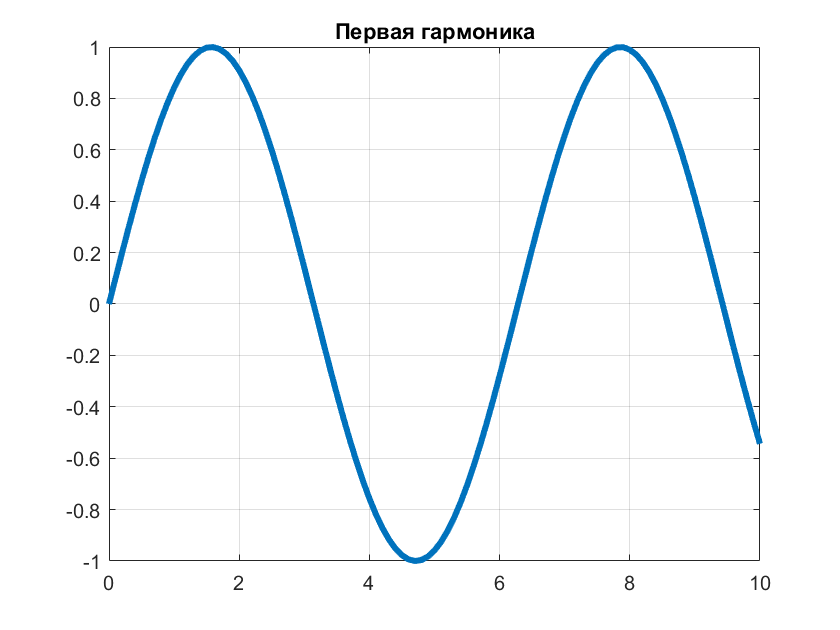

t = 0:.1:10;
y = sin(t);
plot(t,y,'LineWidth',3); grid on;
title('Первая гармоника');

Добавим третью гармонику - синусоиду с частотой в три раза больше фунадментальной. Причём амплитуда - в три раза меньше. Отразим на первом графике отдельные составляющие, а на втором - их сумму.

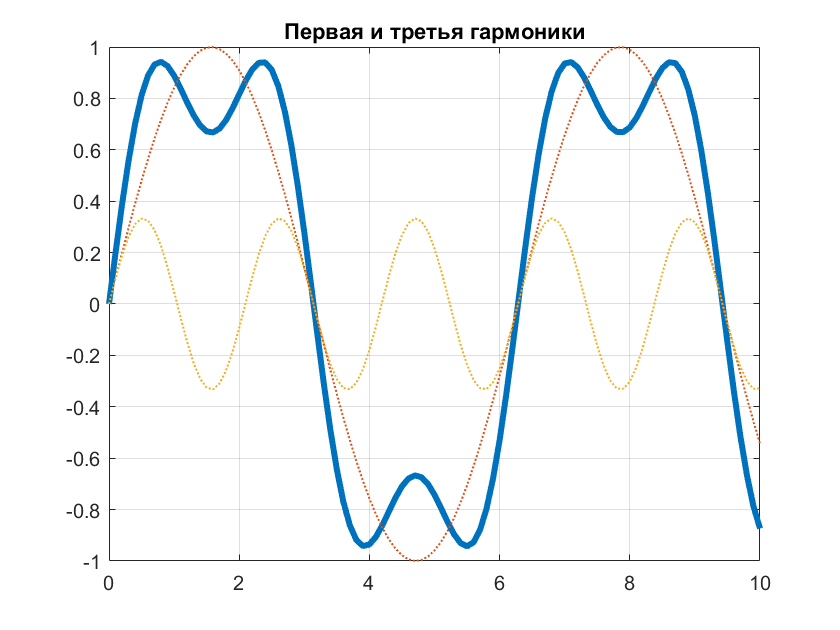

y = sin(t) + sin(3*t)/3;
plot(t,y,'LineWidth',3); grid on; hold on;
plot(t,sin(t),t,sin(3*t)/3,'LineWidth',1,'LineStyle',':');
title('Первая и третья гармоники'); hold off;

Добавляем пятую, седьмую и девятую гармоники. Отразим их и сумму на графиках.

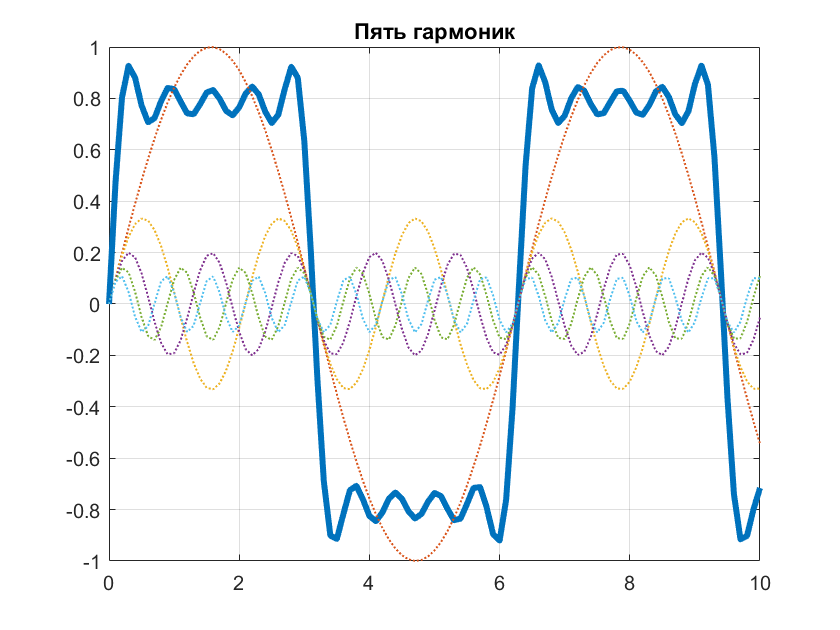

y = sin(t) + sin(3*t)/3 + sin(5*t)/5 + sin(7*t)/7 + sin(9*t)/9;
plot(t,y,'LineWidth',3); grid on; hold on;
plot(t,sin(t),t,sin(3*t)/3,t,sin(5*t)/5,t,sin(7*t)/7,t,sin(9*t)/9,...
    'LineWidth',1,'LineStyle',':');
title('Пять гармоник'); hold off;

Чем больше гармоник мы добавим, тем больше сумма синусоид будет напоминать прямоугольный сигнал.

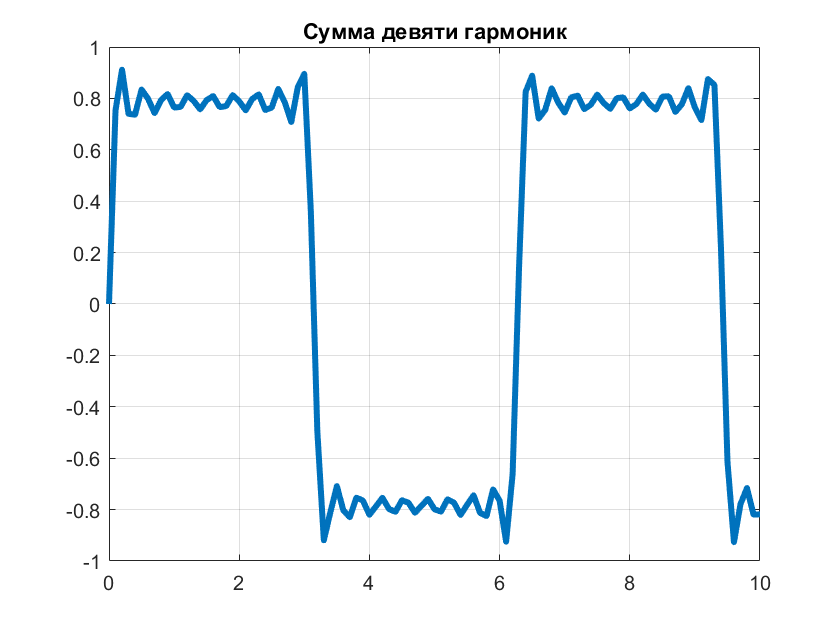

y = sin(t) + sin(3*t)/3 + sin(5*t)/5 + sin(7*t)/7 + sin(9*t)/9 ...
+ sin(11*t)/11 + sin(13*t)/13 + sin(15*t)/15 + sin(17*t)/17;
plot(t,y,'LineWidth',3); grid on;
title('Сумма девяти гармоник');